%f = @(x, y) 1;

## Creat and Display Mesh

nx = 5; ny = 5;
[x, y] = meshgrid(linspace(0, 1, nx), linspace(0, 1, ny));
T.Tri = delaunay(x,y);
T.Nodes = [x(:), y(:)]; T.N = size(T.Nodes, 1); T.Nt = size(T.Tri, 1);
figure(1)
triplot(T.Tri, x, y);
box off; set(gca, 'XTick', [], 'YTick', []);
title('MESH');

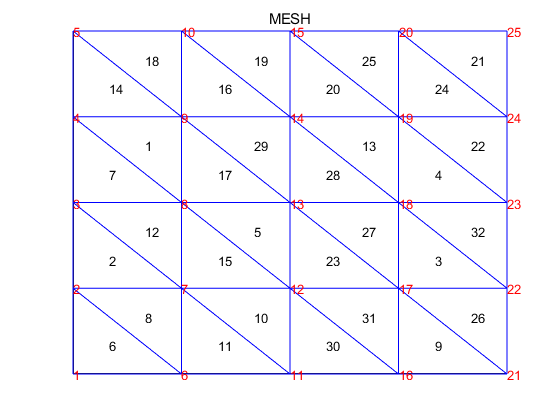

for i = 1:T.Nt
    text((sum(x(T.Tri(i,1:3))))/3,(sum(y(T.Tri(i,1:3))))/3,num2str(i),'Color', 'k');
end

for i = 1:T.N
    text(T.Nodes(i,1), T.Nodes(i,2), num2str(i), 'Color', 'r');
end

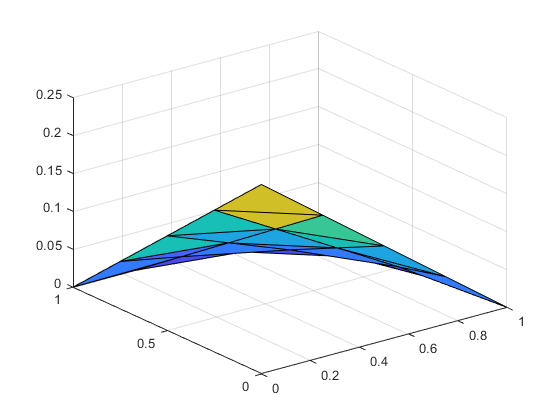

phi21 = @(x, y) (1-x-y+x.*y)/4;
figure(2)
trisurf(T.Tri, T.Nodes(:,1), T.Nodes(:,2), phi21(T.Nodes(:,1), T.Nodes(:,2)));

% Moving Boundary test

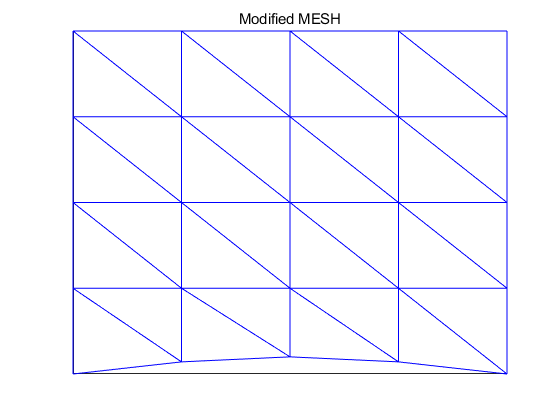

T1 = T;
for i = 1:T.N
    if T1.Nodes(i, 2) == 0
        T1.Nodes(i, 2) = 0.05*sin(T.Nodes(i, 1)*pi);
    end
end
figure(3)
triplot(T1.Tri, T1.Nodes(:,1), T1.Nodes(:,2));
box off; set(gca, 'XTick', [], 'YTick', []);
title('Modified MESH');

## Implement the Structured FEM

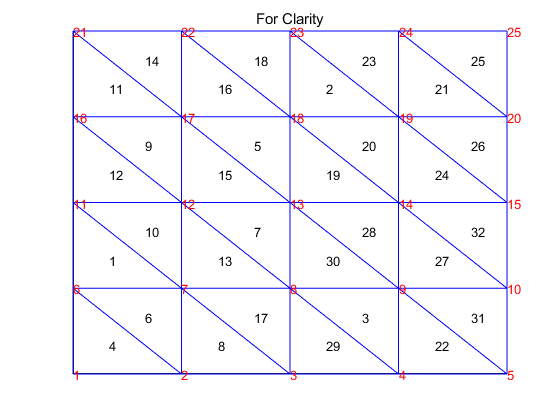

T = RecMesh0(4, 4, 1, 1, 0, 0);
figure(4); ShowMesh(T, [1, 1, 0]); title('For Clarity');

% Set the unknowns

T.Flag = zeros(T.N, 1);
T.Fn = 0;

for i = 1:T.N
    if T.Nodes(i, 2) == 0; T.Flag(i) = 1;
    elseif T.Nodes(i, 1) == 1; T.Flag(i) = 2;
    elseif T.Nodes(i, 2) == 1; T.Flag(i) = 3;
    elseif T.Nodes(i, 1) == 0; T.Flag(i) = 4;
    else; T.Fn = T.Fn+1;
    end
end


% Assemble the Stiffness Matrix

K = zeros(T.Fn, T.Fn);
for i = 1:T.Nt
    j = T.Tri(i, :);
    jp = T.NodePtrs(j);
    cord = T.Nodes(j,:);
    M = [ones(3,1), cord];
    C = inv(M);
    J = cord(2:3,:) - repmat(cord(1,:),2,1);
    A = 0.5*abs(det(J));
    G = C(2:3, :)' * C(2:3,:);
    for s = 1:3
        if T.Flag(j(s)) == 0
            for r = 1:s
                if T.Flag(j(r)) == 0
                    K(min(jp(r),jp(s)), max(jp(r),jp(s))) = K(min(jp(r),jp(s)), max(jp(r),jp(s))) + G(r,s)*A;
                end
            end
        end
    end
end
K = K + triu(K, 1)';

% Compute the Load vector

g = @(x) 1+0.3*sin(pi*x);
F = zeros(T.Fn, 1);
for i = 1:T.Nt
    j = T.Tri(i, :);
    jp = T.NodePtrs(j);
    cord = T.Nodes(j,:);
    M = [ones(3,1), cord];
    C = inv(M);
    J = cord(2:3,:) - repmat(cord(1,:),2,1);
    A = 0.5*abs(det(J));
    G = C(2:3, :)' * C(2:3,:);
    for s = 1:3
        if T.Flag(j(s)) == 0
            for r = 1:3
                if T.Flag(j(r)) == 3
                    F(jp(s)) = F(jp(s)) - G(r,s)*A*g(T.Nodes(j(r),1));
                end
                if T.Flag(j(r)) == 2 || T.Flag(j(r)) == 4
                    F(jp(s)) = F(jp(s)) - G(r,s)*A*(T.Nodes(j(r),2));
                end
            end
        end
    end
end

% Compute and Visualize

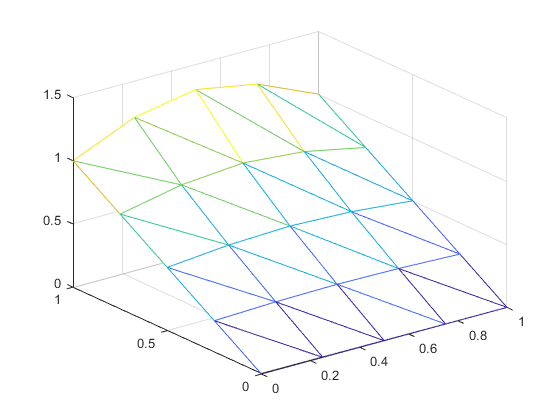

U = K\F;
Z = zeros(T.N, 1);
Z(T.FNodePtrs) = U;
for i = 1:T.N
    if T.Flag(i) == 3
        Z(i) = g(T.Nodes(i, 1));
    end
    if T.Flag(i) == 2 || T.Flag(i) == 4
        Z(i) = T.Nodes(i,2);
    end
end
trimesh(T.Tri, T.Nodes(:,1), T.Nodes(:,2), Z);

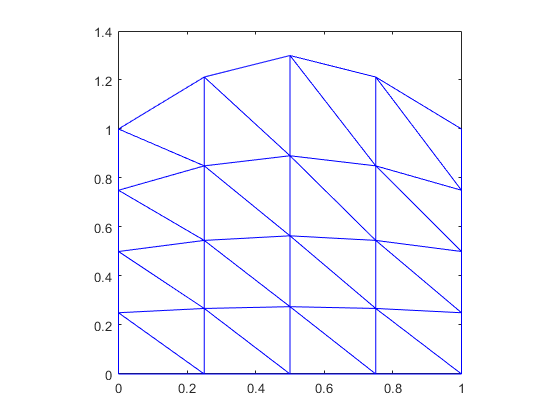

triplot(T.Tri, T.Nodes(:,1), Z);
axis square;

## Prepare to P2 and Higher Order Element

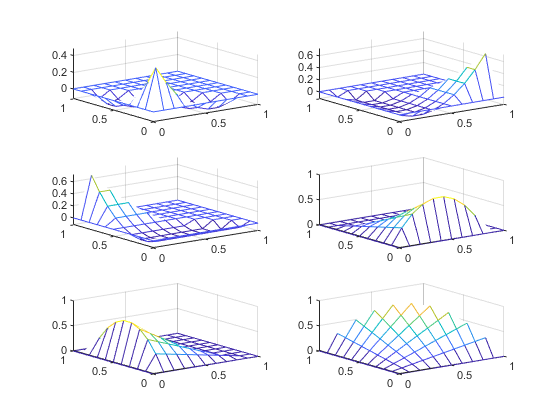

nodes = [0, 0; 1, 0; 0, 1];
p = 2; h = 1/p; nd = 3;
if p==1; nodes4cal = nodes;end
if p>1
    nd = (p+1)*(p+2)/2;
    nodes4cal = zeros(nd ,2);
    nodes4cal(1:3,:) = nodes;
    nodes4cal(4:2+p, :) = [(1:p-1)'/p zeros(p-1, 1)];
    ind = p+2;
    for i = 1:p-1
        numi = p+1-i;
        nodes4cal(ind+1:ind+numi, :) = [(0:numi-1)'/p i*h*ones(numi,1)];
        ind = ind + numi;
    end  
end
M = zeros(nd, nd);
M(:, 1:3) = [ones(nd,1) nodes4cal];
if p>1
    ind = 3;
    for i = 2:p
        for j = 0:i
            ind = ind+1;
            M(:, ind) = nodes4cal(:,1).^(p-j).*nodes4cal(:,2).^j;
        end
    end
end
C = inv(M);
figure
[X, Y] = meshgrid(0:0.1:1, 0:0.1:1);
% Graph of the P2 basis function
for i = 1:nd
    subplot(p+1,p, i)
    s = C(:, i)';
    f = @(x, y) (x>0).*(y>0).*((x+y)<1+1e-3).*(s(1) + s(2)*x + s(3)*y + s(4)*x.^2 + s(5)*x.*y + s(6)*y.^2);
    mesh(X,Y, f(X,Y))
end

## Gaussian-type quadrature

Calculate the 2-d integral

I1 = integral2(@(x,y) 1+0.*x, 0, 1, 0, @(x)1-x);
Ix = integral2(@(x,y) x, 0, 1, 0, @(x)1-x);
Iy = integral2(@(x,y) y, 0, 1, 0, @(x)1-x);
Ix2 = integral2(@(x,y) x.^2, 0, 1, 0, @(x)1-x);
Ixy = integral2(@(x,y) x.*y, 0, 1, 0, @(x)1-x);
Iy2 = integral2(@(x,y) y.^2, 0, 1, 0, @(x)1-x);

fprintf('\t 1 \t x \t y \t x^2 \t xy \t y^2\n');

	 1 	 x 	 y 	 x^2 	 xy 	 y^2


fprintf('\t %.4f %.4f  %.4f  %.4f  %.4f  %.4f', [I1, Ix, Iy, Ix2, Ixy, Iy2]);

	 0.5000 0.1667  0.1667  0.0833  0.0417  0.0833


f = @(x, y) 1; I1 = 1/6*(f(1/2,0)+f(0,1/2)+f(1/2,1/2));
f = @(x, y) x; Ix = 1/6*(f(1/2,0)+f(0,1/2)+f(1/2,1/2));
f = @(x, y) y; Iy = 1/6*(f(1/2,0)+f(0,1/2)+f(1/2,1/2));
f = @(x, y) x.^2; Ix2 = 1/6*(f(1/2,0)+f(0,1/2)+f(1/2,1/2));
f = @(x, y) x.*y; Ixy = 1/6*(f(1/2,0)+f(0,1/2)+f(1/2,1/2));
f = @(x, y) y.^2; Iy2 = 1/6*(f(1/2,0)+f(0,1/2)+f(1/2,1/2));

fprintf('\t %.4f %.4f  %.4f  %.4f  %.4f  %.4f', [I1, Ix, Iy, Ix2, Ixy, Iy2]);

	 0.5000 0.1667  0.1667  0.0833  0.0417  0.0833


w = [0.116786275726379*ones(1, 3), 0.050844906370207*ones(1,3), 0.082851075618374*ones(1,6)];
px = [0.501426509658179; 0.249286745170910; 0.249286745170910; 
    0.873821971016996; 0.063089014491502; 0.063089014491502;
    0.053145049844817; 0.053145049844817; 0.310352451033784;
    0.310352451033784; 0.636502499121399; 0.636502499121399];
py = [0.249286745170910; 0.249286745170910; 0.501426509658179;
    0.063089014491502; 0.063089014491502; 0.873821971016996;
    0.310352451033784; 0.636502499121399; 0.636502499121399;
    0.053145049844817; 0.053145049844817; 0.310352451033784;];

I = w*f(px, py);
for i = 1:3
    f = @(x, y) x.^i;
    R = integral2(f, 0, 1, 0, @(x)1-x)/(w*f(px,py));
    fprintf('\t ind of x:%d ind of y:%d  ratio:%.4f\n',[i, 0, R]);
    for j = 1:3
        f1 = @(x, y) x.^i.*y.^j;
        R = integral2(f, 0, 1, 0, @(x)1-x)/(w*f(px,py));
        fprintf('\t ind of x:%d ind of y:%d  ratio:%.4f\n',[i, j, R]);
    end
end

	 ind of x:1 ind of y:0  ratio:0.5000


	 ind of x:1 ind of y:1  ratio:0.5000
	 ind of x:1 ind of y:2  ratio:0.5000
	 ind of x:1 ind of y:3  ratio:0.5000


	 ind of x:2 ind of y:0  ratio:0.5000


	 ind of x:2 ind of y:1  ratio:0.5000
	 ind of x:2 ind of y:2  ratio:0.5000
	 ind of x:2 ind of y:3  ratio:0.5000


	 ind of x:3 ind of y:0  ratio:0.5000


	 ind of x:3 ind of y:1  ratio:0.5000
	 ind of x:3 ind of y:2  ratio:0.5000
	 ind of x:3 ind of y:3  ratio:0.5000


## Translation test

for i = 1:3
    f = @(x, y) x.^i;
    I1 = integral2(f, 0, 1, 0, @(x)1-x);
    I2 = integral2(f, 0, 2, 0, @(x)2-x);
    fprintf('\t ind of x:%d ind of y:%d  I1:%.4f  I2:%.4f  ratio:%4f\n',[i, 0, I1, I2, I2/I1]);
    for j = 1:3
        f1 = @(x, y) x.^i.*y.^j;
        I1 = integral2(f1, 0, 1, 0, @(x)1-x);
        I2 = integral2(f1, 0, 2, 0, @(x)2-x);
        fprintf('\t ind of x:%d ind of y:%d  I1:%.4f  I2:%.4f  ratio:%.4f\n',[i, j, I1, I2, I2/I1]);
    end
end

	 ind of x:1 ind of y:0  I1:0.1667  I2:1.3333  ratio:8.000000


	 ind of x:1 ind of y:1  I1:0.0417  I2:0.6667  ratio:16.0000
	 ind of x:1 ind of y:2  I1:0.0167  I2:0.5333  ratio:32.0000
	 ind of x:1 ind of y:3  I1:0.0083  I2:0.5333  ratio:64.0000


	 ind of x:2 ind of y:0  I1:0.0833  I2:1.3333  ratio:16.000000


	 ind of x:2 ind of y:1  I1:0.0167  I2:0.5333  ratio:32.0000
	 ind of x:2 ind of y:2  I1:0.0056  I2:0.3556  ratio:64.0000
	 ind of x:2 ind of y:3  I1:0.0024  I2:0.3048  ratio:128.0000


	 ind of x:3 ind of y:0  I1:0.0500  I2:1.6000  ratio:32.000000


	 ind of x:3 ind of y:1  I1:0.0083  I2:0.5333  ratio:64.0000
	 ind of x:3 ind of y:2  I1:0.0024  I2:0.3048  ratio:128.0000
	 ind of x:3 ind of y:3  I1:0.0009  I2:0.2286  ratio:256.0000


## P2 Demo

clear;
nx = 2; ny = 2;
T = RecMesh(nx, ny, 1, 1, 0, 0);
T.Nodes = [T.Nodes; zeros(T.Ne, 2)];
for i = 1:T.Ne
    cord = T.Nodes(T.Edge(i,:),:);
    T.Nodes(i+T.N, :) = mean(cord, 1);
end
T.TC = [T.Tri, T.TrEg+T.N];
T.TP = [T.TC(:,1) T.TC(:,4) T.TC(:,6);
    T.TC(:,4) T.TC(:,2) T.TC(:,5);
    T.TC(:,5) T.TC(:,3) T.TC(:,6);
    T.TC(:,4) T.TC(:,5) T.TC(:,6)];
Nf = (2*nx+1)*(2*ny+1) - (4*nx+4*ny);
T.FNodePtrs = zeros(Nf, 1);
T.CNodePtrs = zeros(4*nx+4*ny ,1);
T.NodePtrs = zeros((2*nx+1)*(2*ny+1), 1);
T.Flag = zeros((2*nx+1)*(2*ny+1), 1);
indf = 0; indc = 0;
for i = 1:(2*nx+1)*(2*ny+1)
    flag = 0;
    if T.Nodes(i, 2) == 0; T.Flag(i) = 1; flag = 1;
    elseif T.Nodes(i, 1) == 1; T.Flag(i) = 2; flag = 1;
    elseif T.Nodes(i, 2) == 1; T.Flag(i) = 3; flag = 1;
    elseif T.Nodes(i, 1) == 0; T.Flag(i) = 4; flag = 1;
    end
    if flag; indc = indc+1; T.CNodePtrs(indc) = i;
    else; indf = indf+1; T.FNodePtrs(indf) = i;
    end
end
T.NodePtrs(T.FNodePtrs) = 1:indf;
T.NodePtrs(T.CNodePtrs) = 1:indc;

% Prepare the Gaussian weights and the reference integral

w = [0.116786275726379*ones(1, 3), 0.050844906370207*ones(1,3), 0.082851075618374*ones(1,6)];
px = [0.501426509658179; 0.249286745170910; 0.249286745170910; 
    0.873821971016996; 0.063089014491502; 0.063089014491502;
    0.053145049844817; 0.053145049844817; 0.310352451033784;
    0.310352451033784; 0.636502499121399; 0.636502499121399];
py = [0.249286745170910; 0.249286745170910; 0.501426509658179;
    0.063089014491502; 0.063089014491502; 0.873821971016996;
    0.310352451033784; 0.636502499121399; 0.636502499121399;
    0.053145049844817; 0.053145049844817; 0.310352451033784;];

Px = [zeros(12,1), ones(12,1), zeros(12,1), 2*px, py, zeros(12,1)];
Py = [zeros(12,1), zeros(12,1), ones(12,1), zeros(12,1), px, 2*py];

cord = [0, 0; 1, 0; 0, 1; 1/2, 0; 1/2, 1/2; 0, 1/2];
M = [ones(6,1), cord, cord(:, 1).^2, cord(:, 1).*cord(:, 2), cord(:, 2).^2];
C = inv(M); % Coefficients of basis funcitons

## Assembling the Stiff Matrix

K = zeros(Nf, Nf);
for i = 1:T.Nt
    j = T.Tri(i, :);
    cord = T.Nodes(j,:);
    J = (cord(2:3,:) - repmat(cord(1,:),2,1))';
    A = abs(det(J));
    J0 = inv(J);
    j = T.TC(i, :);
    jp = T.NodePtrs(j);
    for s = 1:6
        if T.Flag(j(s)) == 0
            c1 = C(:, s);
            for r = 1:s
                if T.Flag(j(r)) == 0
                    c2 = C(:, r);
                    V = [Px*c1 Py*c1 Px*c2 Py*c2]; % Value of derivatives of basis functions
                    I = w*((V(:, 1:2)*J0(:,1)).*(V(:, 3:4)*J0(:,1))+(V(:, 1:2)*J0(:,2)).*(V(:, 3:4)*J0(:,2)))/2;
                    K(min(jp(r),jp(s)), max(jp(r),jp(s))) = K(min(jp(r),jp(s)), max(jp(r),jp(s))) + I*A;
                end
            end
        end
    end
end
K = K + triu(K, 1)';

% Compute the Load vector

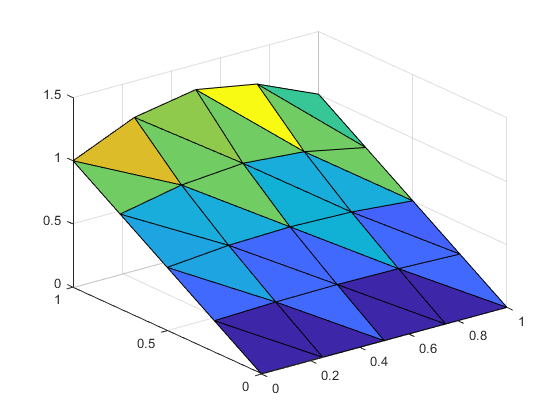

g = @(x) 1+0.3*sin(pi*x);
F = zeros(Nf, 1);
for i = 1:T.Nt
    j = T.Tri(i, :);
    cord = T.Nodes(j,:);
    J = (cord(2:3,:) - repmat(cord(1,:),2,1))';
    A = abs(det(J));
    J0 = inv(J);
    j = T.TC(i, :);
    jp = T.NodePtrs(j);
    for s = 1:6
        if T.Flag(j(s)) == 0
            c1 = C(:, s);
            for r = 1:6
                if T.Flag(j(r)) == 3
                    c2 = C(:, r);
                    V = [Px*c1 Py*c1 Px*c2 Py*c2]; % Value of derivatives of basis functions
                    I = w*((V(:, 1:2)*J0(:,1)).*(V(:, 3:4)*J0(:,1))+(V(:, 1:2)*J0(:,2)).*(V(:, 3:4)*J0(:,2)))/2;
                    F(jp(s)) = F(jp(s)) - I*A*g(T.Nodes(j(r),1));
                end
                if T.Flag(j(r)) == 2 || T.Flag(j(r)) == 4
                    c2 = C(:, r);
                    V = [Px*c1 Py*c1 Px*c2 Py*c2]; % Value of derivatives of basis functions
                    I = w*((V(:, 1:2)*J0(:,1)).*(V(:, 3:4)*J0(:,1))+(V(:, 1:2)*J0(:,2)).*(V(:, 3:4)*J0(:,2)))/2;
                    F(jp(s)) = F(jp(s)) - I*A*(T.Nodes(j(r),2));
                end
            end
        end
    end
end

U = K\F;
Z = zeros(T.N, 1);
Z(T.FNodePtrs) = U;
Z(T.Flag==2) = T.Nodes(T.Flag==2, 2);
Z(T.Flag==3) = g(T.Nodes(T.Flag==3 ,1));
Z(T.Flag==4) = T.Nodes(T.Flag==4, 2);

figure(2); trisurf(T.TP, T.Nodes(:,1), T.Nodes(:,2), Z);